for i=0:14
    file = append(int2str(i),'.mp3');
    [signal, F_s] = audioread(file);
    i
    %signal=signal(:,1);
    signal= bandpass(signal(:,1),[1000,10000], F_s);
    [Xmat,Tmat]=syllablecutmod(signal, F_s,200,5,500,2000,100);
    figure(200+i)
    NFFT=2048;
    [R,f]=periodogram(Xmat(:,1),[],NFFT,F_s);
    plot(f,10*log10(R))
end
%[signal, F_s] = audioread('');
%signal=signal(:,1);
%time = [0:1./F_s:(length(signal)-1)./F_s];
%figure(1);
%plot(time, signal(:,1));
%xlabel('Time (s)')
%ylabel('Amplitude')
%title('Signal in time domain')
%figure(2)


%soundsc(Xmat(:,1), F_s);
figure(50)
NFFT=2048;
[R,f]=periodogram(highpass(Xmat(:,1),1000, F_s),[],NFFT,F_s);
plot(f,10*log10(R))
soundsc(highpass(Xmat(:,1),1000, F_s), F_s);

[signal, F_s] = audioread('6.mp3');
soundsc(signal(:,1), F_s);
time = [0:1./F_s:(length(signal)-1)./F_s];
figure(300)
plot(time, highpass(signal(:,1),1000, F_s))
figure(301)
plot(time, signal(:,1))

soundsc(signal(:,1), F_s);

[signal, F_s] = audioread('14.mp3');
soundsc(signal(:,1), F_s);
signal= highpass(signal(:,1),1000, F_s)
%figure(100)
figure(500)
[Xmat,Tmat]=syllablecut(signal, F_s,200,5,500);
%soundsc(Xmat(:,1), F_s);

soundsc(signal, F_s);

window=2048;
NFFT=8192;
noverlap=1024;
figure(111)
spectrogram(Xmat(:,2),window,noverlap,NFFT,F_s, 'yaxis');

i=5

i = 5

    file = append(int2str(i),'.mp3');
    [signal, F_s] = audioread(file);
    i

i = 5

maxt = 537144

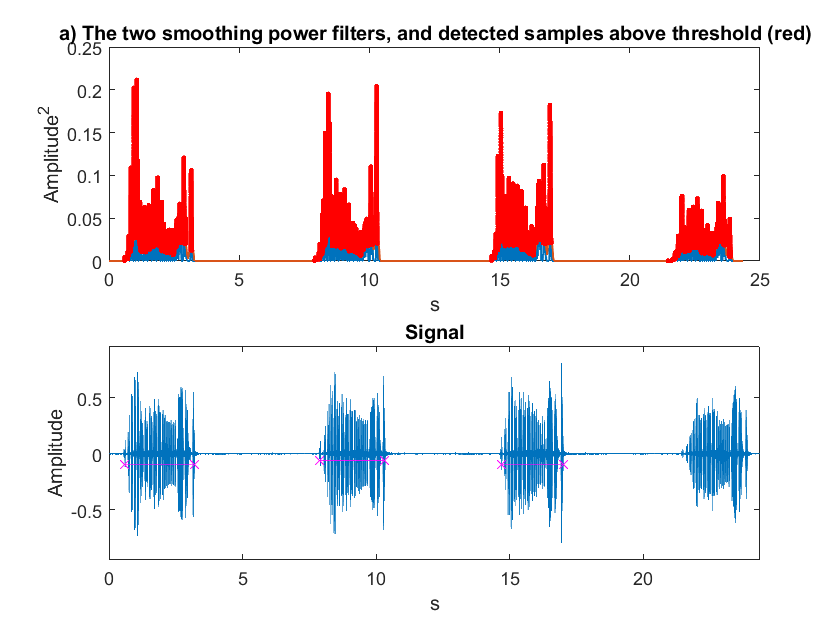

    signal=signal(:,1);
    signal=signal(1:2:end);
    F_s=F_s/2;
    signal= bandpass(signal,[1000,10000], F_s);
    [Xmat,Tmat]=syllablecutmod(signal, F_s,200,5,500,2000,100);

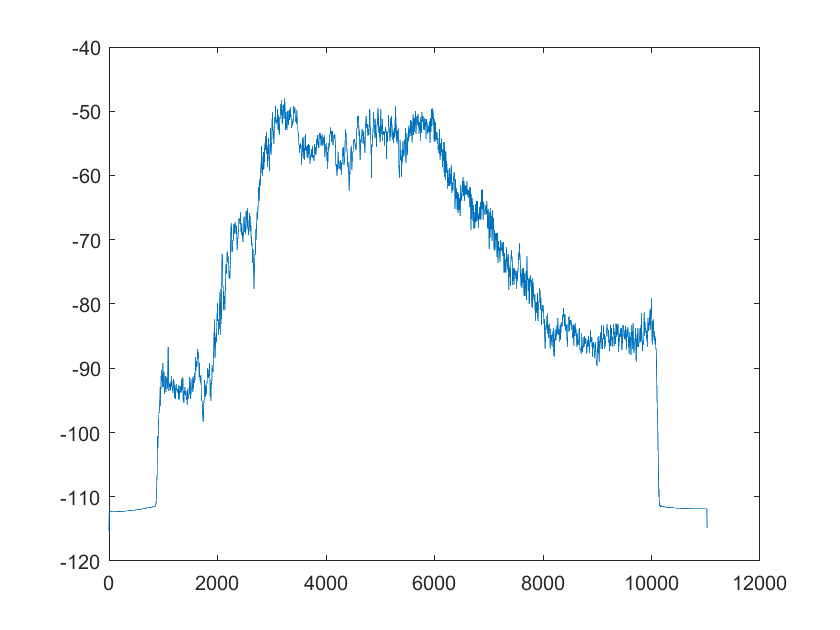

%     figure(200+i)
%     NFFT=2048;
%     [R,f]=periodogram(Xmat(:,1),[],NFFT,F_s);
%     plot(f,10*log10(R))
    figure(222)
    [pxx, f] = pwelch(Xmat(:,1),5000,3000,5000,F_s);
plot(f, 10*log10(pxx));

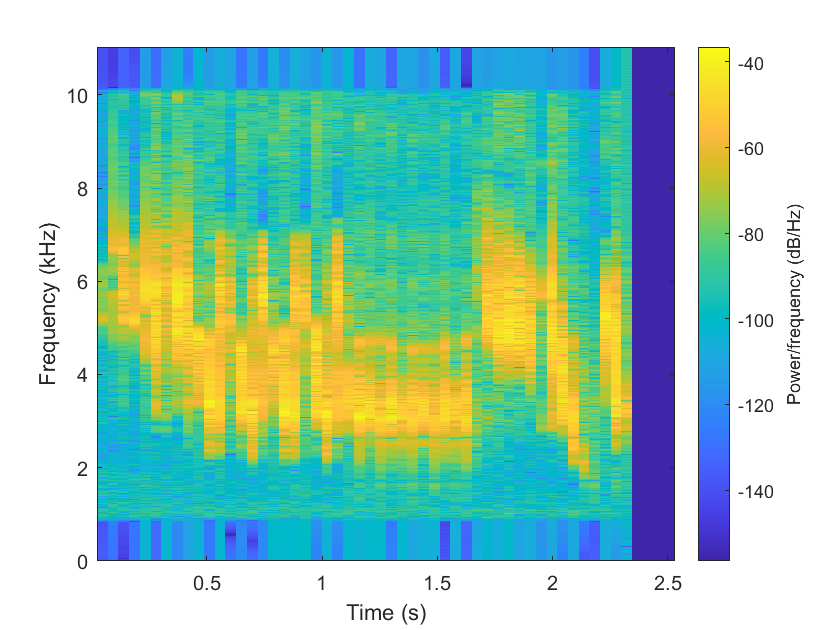

%soundsc(Xmat(:,3),F_s)
window=2048;
NFFT=8192;
noverlap=1024;
spectrogram(Xmat(:,3),window,noverlap,NFFT,F_s, 'yaxis');

%(length(remove0(Xmat(:,2)))-1)/F_s
%[signal, F_s] = audioread('');
%signal=signal(:,1);
%time = [0:1./F_s:(length(signal)-1)./F_s];
%figure(1);
%plot(time, signal(:,1));
%xlabel('Time (s)')
%ylabel('Amplitude')
%title('Signal in time domain')
%figure(2)